Plot sample data

% P = rand([3 3]);
% PQ = [0.5 0.5 0.5; 0.1 0.1 0.1; 0.9 0.9 0.9  ];
% [k,dist] = dsearchn(P,PQ);
% 
% plot3(P(:,1),P(:,2),P(:,3),'ko')
% hold on
% plot3(PQ(:,1),PQ(:,2),PQ(:,3),'*g')
% hold on
% plot3(P(k,1),P(k,2),P(k,3),'*r')
% legend('Data Points','Query Points','Nearest Points','Location','sw')

hold off

Algorithm

Line = zeros(100,3);
Line_yaw = zeros(100,3);
for i = 1:100
    Line(i,1) = i/100.;
    
    Line_yaw(i,1) = 2.;
    Line_yaw(i,2) = i/100. - 0.5;
end

tic
aligned_Line = icp(Line,Line_yaw,0.1,1);

errorSum = 0.0254

count = 1

toc

경과 시간은 0.108850초입니다.


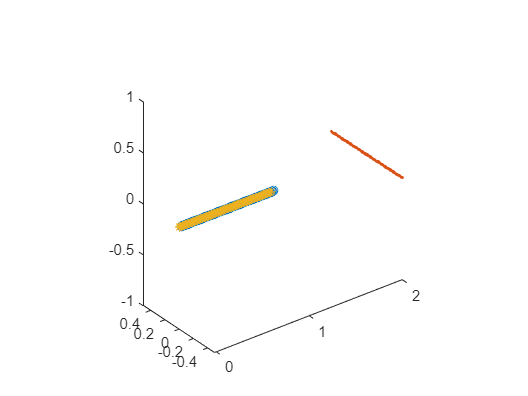


plot3(Line(:,1),Line(:,2),Line(:,3),'o')
hold on
plot3(Line_yaw(:,1),Line_yaw(:,2),Line_yaw(:,3),'.')
plot3(aligned_Line(:,1),aligned_Line(:,2),aligned_Line(:,3),'*')
axis equal
hold off



tic
aligned_corner_yaw = icp(Corner,Corner_yaw,0.1,1);

errorSum = 3.2422

count = 3

toc

경과 시간은 0.014645초입니다.


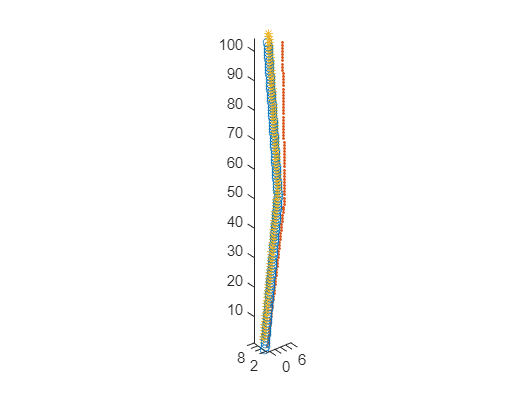


plot3(Corner(:,1),Corner(:,2),Corner(:,3),'o')
hold on
plot3(Corner_yaw(:,1),Corner_yaw(:,2),Corner_yaw(:,3),'.')
plot3(aligned_corner_yaw(:,1),aligned_corner_yaw(:,2),aligned_corner_yaw(:,3),'*')
axis equal
hold off



tic
aligned_circle = icp(Circle,Circle_x_y_yaw,0.1,1);

errorSum = 4.8850

count = 3

toc

경과 시간은 0.028247초입니다.


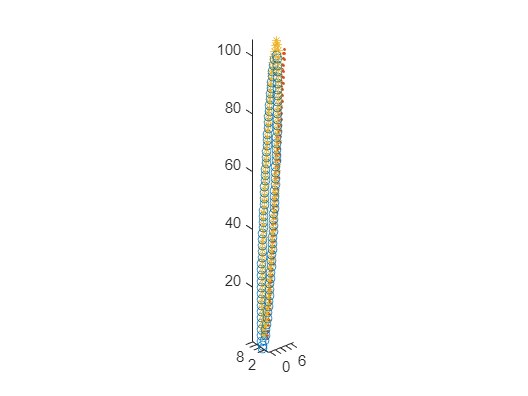


plot3(Circle(:,1),Circle(:,2),Circle(:,3),'o')
hold on
plot3(Circle_x_y_yaw(:,1),Circle_x_y_yaw(:,2),Circle_x_y_yaw(:,3),'.')
plot3(aligned_circle(:,1),aligned_circle(:,2),aligned_circle(:,3),'*')
axis equal
hold off



tic
aligned_rectangle_yaw = icp(Rectangular,Rectangular_x_y_yaw,0.1,1);

errorSum = 0.7351

count = 3

toc

경과 시간은 0.004009초입니다.


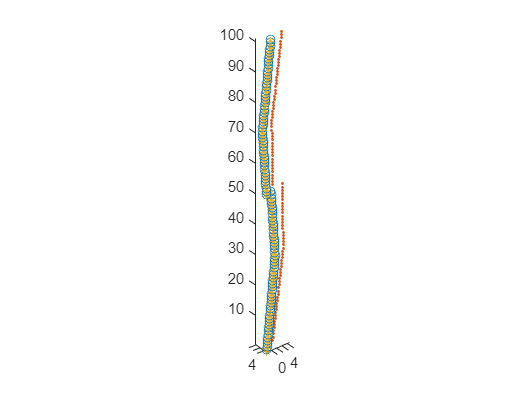


plot3(Rectangular(:,1),Rectangular(:,2),Rectangular(:,3),'o')
hold on
plot3(Rectangular_x_y_yaw(:,1),Rectangular_x_y_yaw(:,2),Rectangular_x_y_yaw(:,3),'.')
plot3(aligned_rectangle_yaw(:,1),aligned_rectangle_yaw(:,2),aligned_rectangle_yaw(:,3),'*')
axis equal
hold off


tic
aligned_sinuous = icp(Sinuous,Sinuous_x_y_yaw,0.1,1);

errorSum = 3.0935

count = 3

toc

경과 시간은 0.005229초입니다.


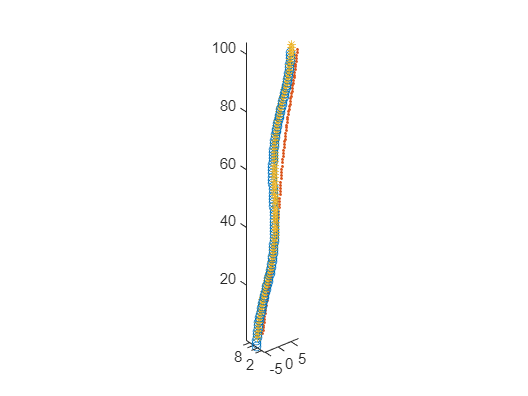


plot3(Sinuous(:,1),Sinuous(:,2),Sinuous(:,3),'o')
hold on
plot3(Sinuous_x_y_yaw(:,1),Sinuous_x_y_yaw(:,2),Sinuous_x_y_yaw(:,3),'.')
plot3(aligned_sinuous(:,1),aligned_sinuous(:,2),aligned_sinuous(:,3),'*')
axis equal
hold off

functions

function aligned_points = icp(origin,target,threshold,samplingMethod)
  
    OriginData = origin(:,1:3)';
    FixedData = target(:,1:3)';
    errorSum = 0;
    count = 0;
    sampling_method = samplingMethod; % 0: Use all 1: RandomSample 2: Normal-space
    while true

        % Sampling
        switch sampling_method
            case 0 % Use all
                SampledFixed = FixedData;

            case 1 % Random Sample
                sampling_rate = 0.5;
                sampling_num = round(length(FixedData')*sampling_rate);
                sampleIndex = randi(length(FixedData'),1,sampling_num);
                SampledFixed = FixedData(:,sampleIndex);

            case 2 % Normal space
                sampling_rate = 0.5;
                sampling_num = round(length(FixedData')*sampling_rate);
                sampleIndex = zeros(1,sampling_num);
%                 for idx = 1:length(FixedData)
%                     
%                 end

        end

        
%         SampledFixed = FixedData;
        lenSampleFixed = length(SampledFixed');
        
        % find nearest points idx
        P = OriginData';
        PQ = SampledFixed';
        [k,dist] = dsearchn(P,PQ); % k is index of P element which are closest to each PQ
        dist;
        avg_dist = mean(dist);

        % re Indexing
        reIndexedOrign = zeros(3,length(length(k)));
        for idx = 1:length(k)
            reIndexedOrign(:,idx) = OriginData(:,k(idx));
        end
        
        % Center of Mass
        centerMass_1 = zeros(3,length(reIndexedOrign'));
        centerMass_2 = zeros(3,length(SampledFixed'));
        
        avg_x_1 = mean(reIndexedOrign(1,:));
        avg_y_1 = mean(reIndexedOrign(2,:));
        avg_z_1 = mean(reIndexedOrign(3,:));

        avg_x_1 = mean(OriginData(1,:));
        avg_y_1 = mean(OriginData(2,:));
        avg_z_1 = mean(OriginData(3,:));
        
        u_1 = [avg_x_1 avg_y_1 avg_z_1]';
%         centerMass_1(1,:)
%         reIndexedOrign(1,:)
        centerMass_1(1,:) = reIndexedOrign(1,:) - avg_x_1;
        centerMass_1(2,:) = reIndexedOrign(2,:) - avg_y_1;
        centerMass_1(3,:) = reIndexedOrign(3,:) - avg_z_1;
        
        avg_x_2 = mean(SampledFixed(1,:));
        avg_y_2 = mean(SampledFixed(2,:));
        avg_z_2 = mean(SampledFixed(3,:));
        
        u_2 = [avg_x_2 avg_y_2 avg_z_2]';
        
        centerMass_2(1,:) = SampledFixed(1,:) - avg_x_2;
        centerMass_2(2,:) = SampledFixed(2,:) - avg_y_2;
        centerMass_2(3,:) = SampledFixed(3,:) - avg_z_2;
        

        % Singular Value Decomposition
        W = zeros(3,3);
        
%         U = zeros(3,3);
%         S = zeros(3,3);
%         V = zeros(3,3);
%         
%         R = zeros(3,3);
%         T = zeros(3,1);
        
        for i = 1:lenSampleFixed
            W = W + centerMass_1(:,i)*centerMass_2(:,i)';
        end
        
        
        [U,S,V] = svd(W);
        
        % Adapt R t 
        R = U*V';
        T = u_1 - R*u_2;
        
        FixedData = R*FixedData + T;
        
        % Sum of the square errors
        
        for i = 1:length(OriginData(1,:))
            errorSum = errorSum + sqrt((OriginData(1,i)-FixedData(1,i))^2 + (OriginData(2,i)-FixedData(2,i))^2 ...
                + (OriginData(3,i)-FixedData(3,i))^2 );
        end
        errorSum = errorSum/length(OriginData(1,:));
        count = count +1;

        % Break out
        if errorSum <= threshold || count >= 3
            errorSum
            count
            break;
        end
    end
    
    % End of function
    aligned_points = FixedData';
end